# 关于第一次编程作业的说明：

- 请注意完成编程作业中的讨论，可以通过注释、嵌入文本、额外文件等任意形式完成；

- 在第一次编程作业中如果使用工具箱，可以通过截图等形式提交结果；

- 为了简化大家的代码过程，我向大家提供了第一次编程作业的.mlx文件，里面提供了关于.mlx文件的说明；

- 大家仍然可以使用任意形式matlab代码完成第一次编程作业，并不限制大家一定需要使用该模版，但仍然需要大家注明题号；

感谢大家的配合！

# template

- 本文件已经对每道编程题目通过分节符分节，可以单独通过”运行节“命令执行一道题目（选中）的代码，或通过”运行“命令执行整个文件；

- 关于很多同学在.mlx中遇到的图像错位问题：主要原因是在单个脚本文件中，工作区和图像设定是始终向后保持的。在之前的题目中使用subplot()画多个子图，之后的题目中画图时会出现在之前的子图中，可以在每个题目的代码前通过clf命令清除图像窗口；

clear
clf

% (a)
x = 0:pi/100:2*pi;  
y = sin(x)

y =          0    0.0314    0.0628    0.0941    0.1253    0.1564    0.1874    0.2181    0.2487    0.2790    0.3090    0.3387    0.3681    0.3971    0.4258    0.4540    0.4818    0.5090    0.5358    0.5621    0.5878    0.6129    0.6374    0.6613    0.6845    0.7071    0.7290    0.7501    0.7705    0.7902    0.8090    0.8271    0.8443    0.8607    0.8763    0.8910    0.9048    0.9178    0.9298    0.9409    0.9511    0.9603    0.9686    0.9759    0.9823    0.9877    0.9921    0.9956    0.9980    0.9995


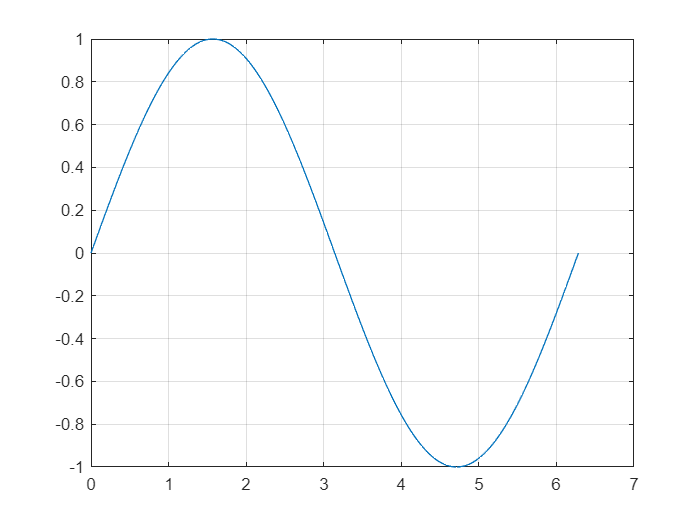

plot(x,y), grid;

% (b)
% 讨论分析

或通过内置文本讨论分析。如需插入公式，可以使用方程或LaTex方程 $F(s)=\int_0^\infty e^{-st} f(t) {\rm d}t$。

如需插入截图，直接粘贴即可。

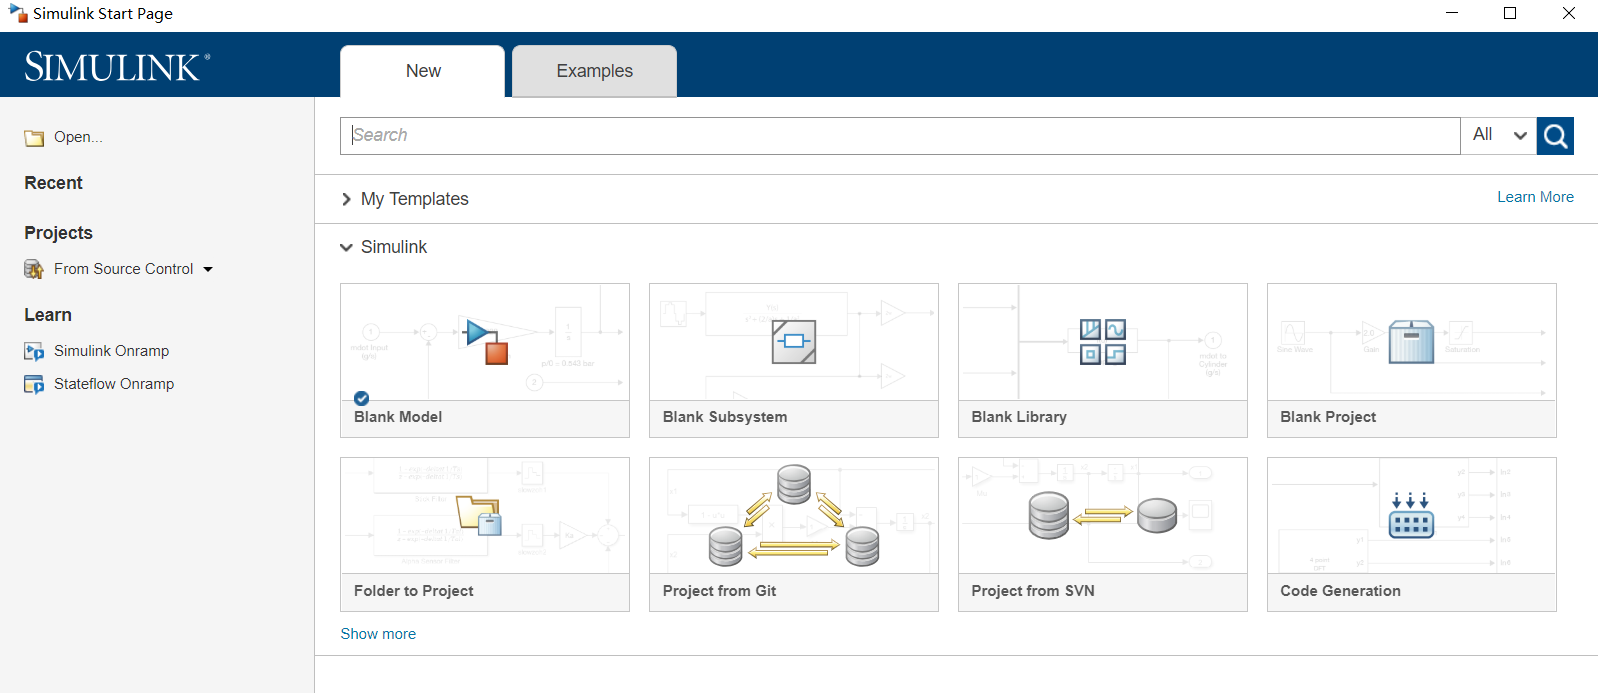

# 2-1

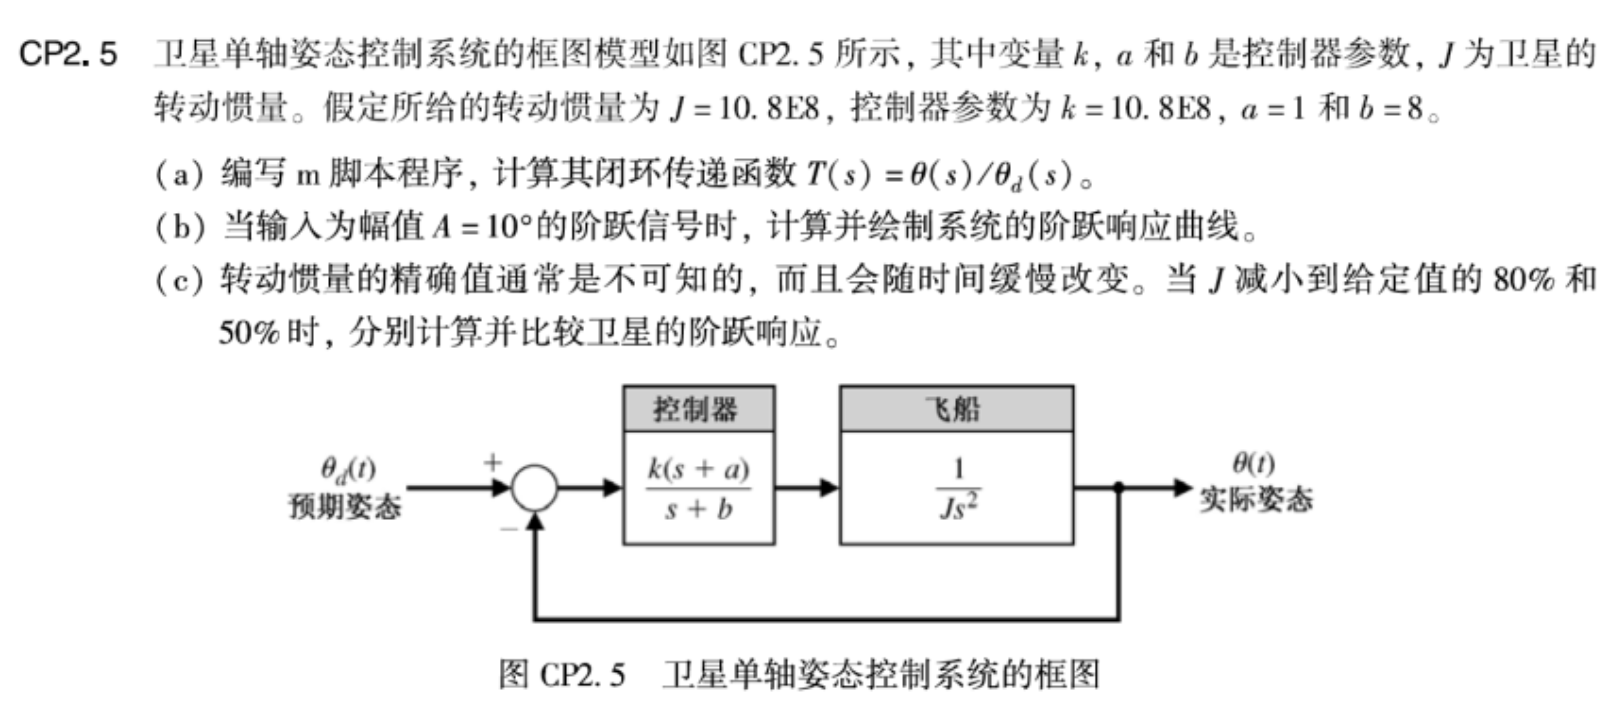

clf

% define parameters
J = 10.8E8;
k = 10.8E8;
a = 1;
b = 8;


% 3. 100%, 80% and 50% J
sys = get_sys_2_1(J, k, a, b)

sys =
 
                1.08e09 s + 1.08e09
  -----------------------------------------------
  1.08e09 s^3 + 8.64e09 s^2 + 1.08e09 s + 1.08e09
 
Continuous-time transfer function.



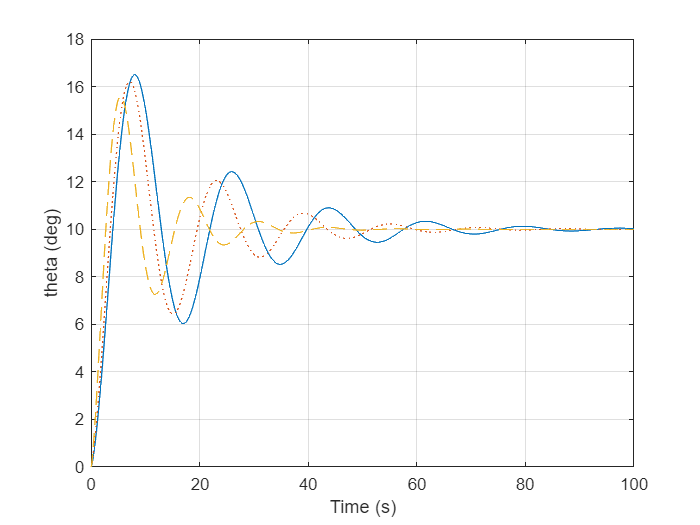

t = 0:0.1:100;
y1 = get_y_2_1(get_sys_2_1(J, k, a, b), t);
y2 = get_y_2_1(get_sys_2_1(0.8 * J, k, a, b), t);
y3 = get_y_2_1(get_sys_2_1(0.5 * J, k, a, b), t);
plot(t, y1, t, y2, ':', t, y3, '--'), grid
xlabel('Time (s)')
ylabel('theta (deg)')

由于函数只能放在末尾, 这里我就先注释掉, 然后把函数放末尾了...

% % 1. calculate transfer function
% function sys = get_sys_2_1(J, k, a, b)
%     num1 = [k, k * a];
%     den1 = [1, b];
%     num2 = 1;
%     den2 = [J, 0, 0];

%     [num, den] = series(num1, den1, num2, den2);
%     [num, den] = feedback(num, den, 1, 1, -1);
%     sys = tf(num, den);
% end


% % 2. draw the curve with step sinal A = 10
% function y = get_y_2_1(sys, t)
%     opt = stepDataOptions('StepAmplitude', 10);
%     [y, ~] = step(sys, t, opt);
% end

# 2-2

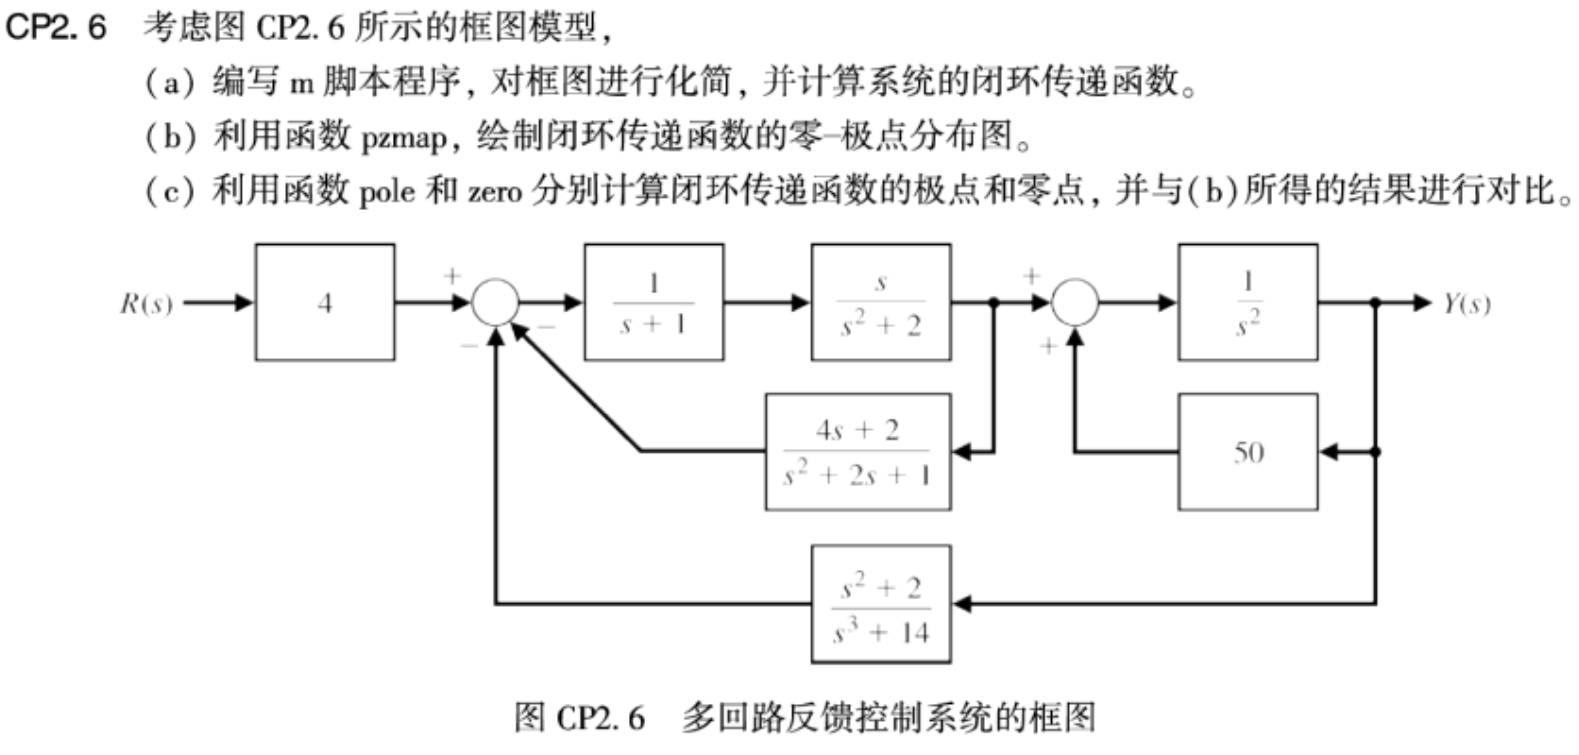

clf

% basic sys
num1 = 4; den1 = 1; sys1 = tf(num1, den1);
num2 = 1; den2 = [1 1]; sys2 = tf(num2, den2);
num3 = [1 0]; den3 = [1 0 2]; sys3 = tf(num3, den3);
num4 = 1; den4 = [1 0 0]; sys4 = tf(num4, den4);
num5 = [4 2]; den5 = [1 2 1]; sys5 = tf(num5, den5);
num6 = 50; den6 = 1; sys6 = tf(num6, den6);
num7 = [1 0 2]; den7 = [1 0 0 14]; sys7 = tf(num7, den7);


% 1. compose sys
sysc1 = series(sys2, sys3);
sysc2 = feedback(sysc1, sys5);
sysc3 = feedback(sys4, sys6, 1);
sysc4 = series(sysc2, sysc3);
sysc5 = feedback(sysc4, sys7);
sys = series(sys1, sysc5);
sys

sys =
 
                             4 s^6 + 8 s^5 + 4 s^4 + 56 s^3 + 112 s^2 + 56 s
  -----------------------------------------------------------------------------------------------------
  s^10 + 3 s^9 - 45 s^8 - 125 s^7 - 200 s^6 - 1177 s^5 - 2344 s^4 - 3485 s^3 - 7668 s^2 - 5598 s - 1400
 
Continuous-time transfer function.



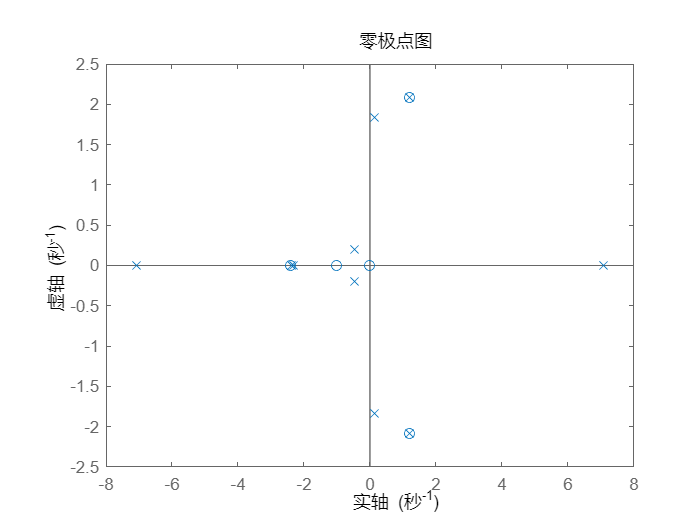

% 2. pzmap
pzmap(sys)

% 3. pole and zero
p = pole(sys);
z = zero(sys);
p

p =    7.0709 + 0.0000i
  -7.0713 + 0.0000i
   1.2051 + 2.0863i
   1.2051 - 2.0863i
   0.1219 + 1.8374i
   0.1219 - 1.8374i
  -2.3933 + 0.0000i
  -2.3333 + 0.0000i
  -0.4635 + 0.1997i
  -0.4635 - 0.1997i


z

z =    0.0000 + 0.0000i
   1.2051 + 2.0872i
   1.2051 - 2.0872i
  -2.4101 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


# 2-3

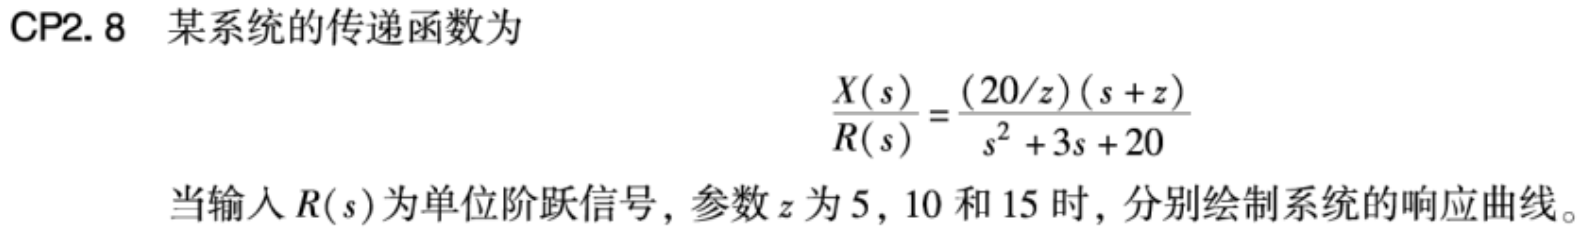

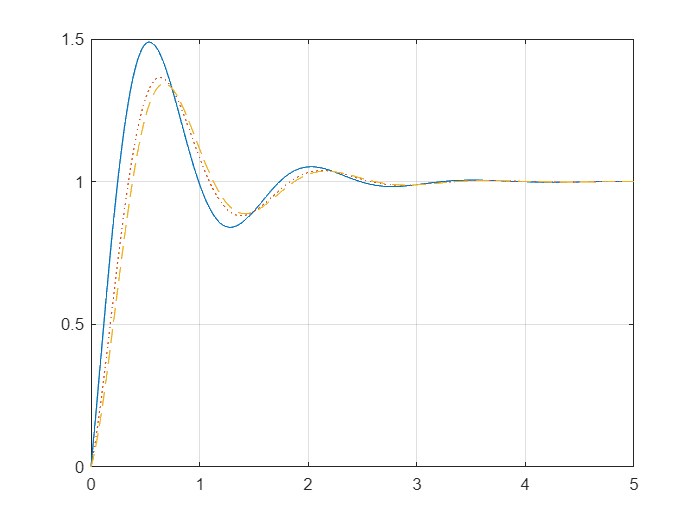

% z = 5, 10, 15
t = 0:0.005:5;
y1 = get_y_2_3(get_sys_2_3(5), t);
y2 = get_y_2_3(get_sys_2_3(10), t);
y3 = get_y_2_3(get_sys_2_3(15), t);     
plot(t, y1, t, y2, ':', t, y3, '--'), grid

由于函数只能放在末尾, 这里我就先注释掉, 然后把函数放末尾了...

% % 1. calculate transfer function
% function sys = get_sys_2_3(z)
%     num = [20 / z, 20];
%     den = [1, 3, 20];
%     sys = tf(num, den);
% end


% % 2. draw the curve with step sinal
% function y = get_y_2_3(sys, t)
%     [y, ~] = step(sys, t);
% end

# 2-4

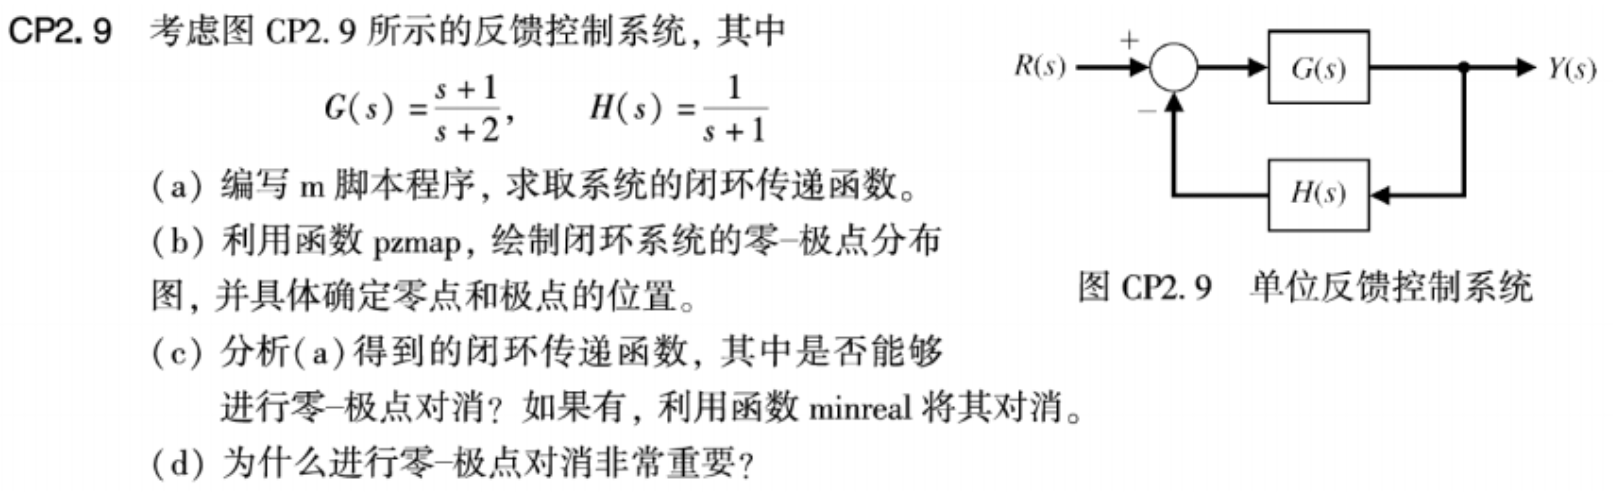

% 1.
num_g = [1 1]; den_g = [1 2]; sys_g = tf(num_g, den_g);
num_h = 1; den_h = [1 1]; sys_h = tf(num_h, den_h);
sys = feedback(sys_g, sys_h);
sys

sys =
 
  s^2 + 2 s + 1
  -------------
  s^2 + 4 s + 3
 
Continuous-time transfer function.



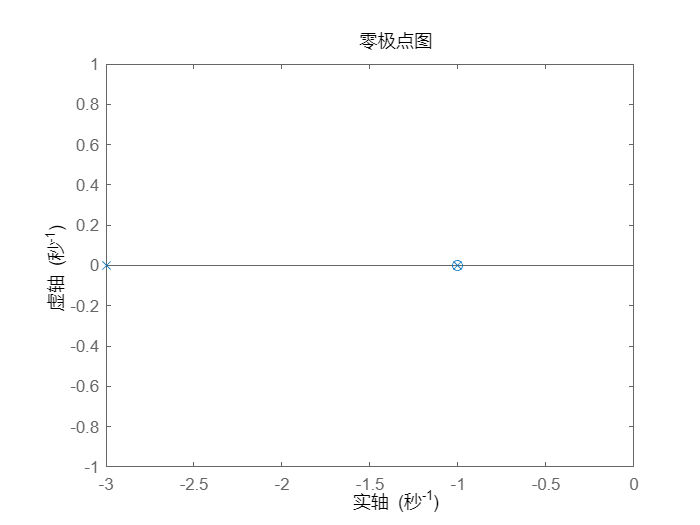

% 2.
pzmap(sys);

p = pole(sys);
z = zero(sys);
p

p =     -3
    -1


z

z =     -1
    -1


% 3.
sysm = minreal(sys);
sysm

sysm =
 
  s + 1
  -----
  s + 3
 
Continuous-time transfer function.



# 5-1

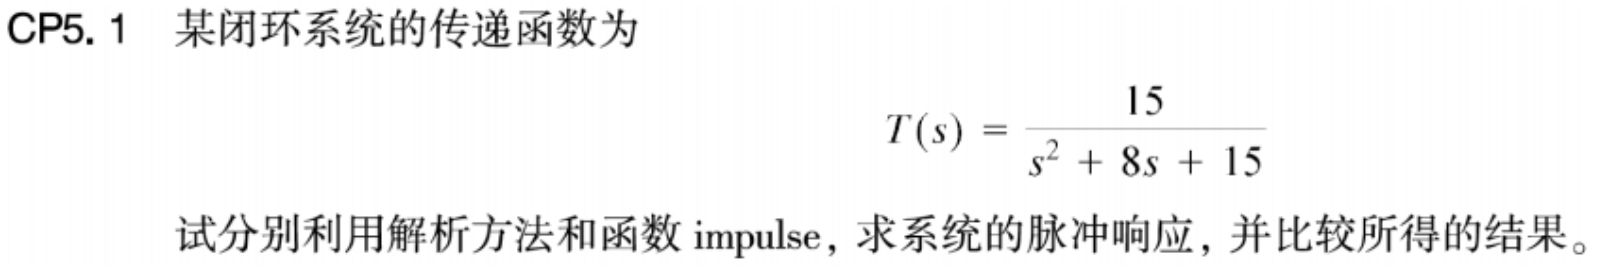

`由于脉冲信号的拉普拉斯变换为 `$R(s) = 1$`, 因此有`


$$\displaystyle
Y(s) = \frac{15}{s^{2}+8s+15}R(s) = \frac{15}{(s+3)(s+5)} = \frac{15}{2 (s + 3)} - \frac{15}{2 (s + 5)}$$


`因此, 进行逆拉普拉斯变换可得`


$$\displaystyle 
y(t) = \frac{15}{2}e^{-3t} - \frac{15}{2}e^{-5t}
$$


`此为解析方法的结果.`

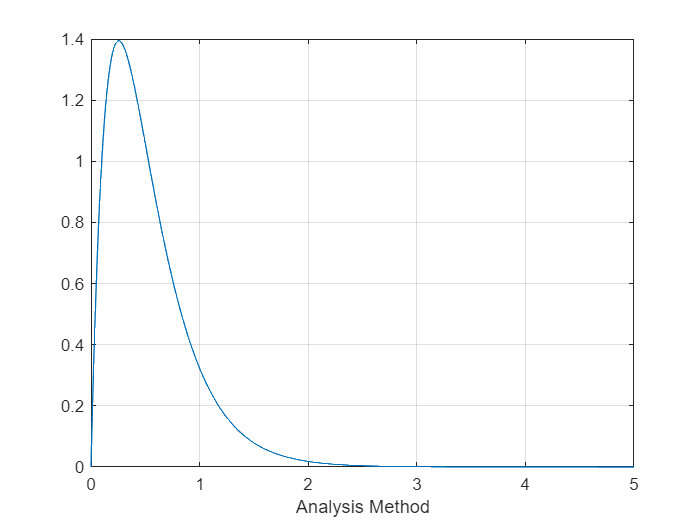

t = 0:0.005:5;
num = 15; den = [1 8 15]; sys = tf(num,den);

% y(t) = \frac{15}{2}e^{-3t} - \frac{15}{2}e^{-5t}
y1 = (15 / 2) * exp(-3 * t) - (15 / 2) * exp(-5 * t);
plot(t, y1), grid
xlabel('Analysis Method')

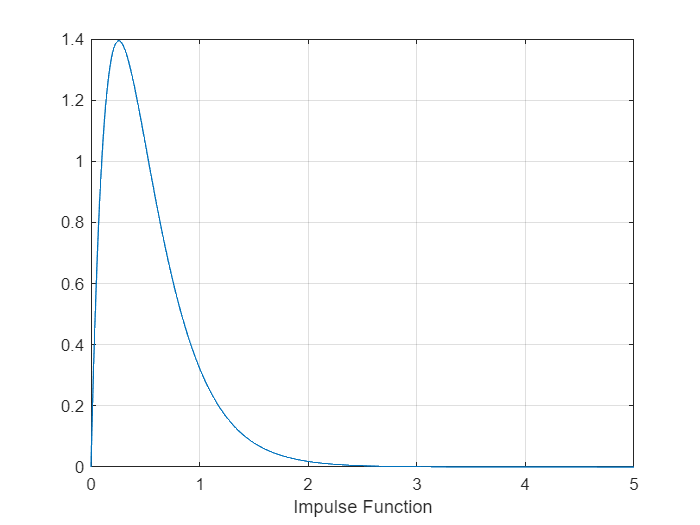

y2 = impulse(sys, t);
plot(t, y2), grid
xlabel('Impulse Function')

可以看出, 解析方法和函数 impulse 的结果是一致的.

# 5-2

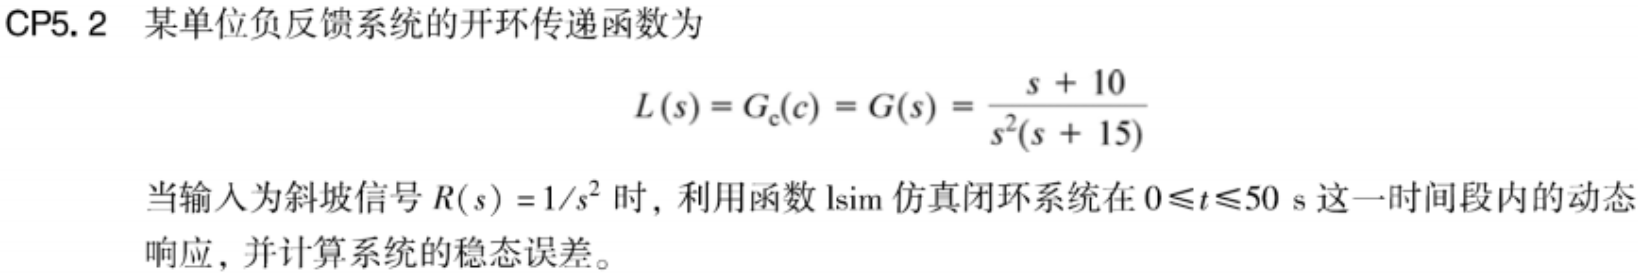

`由于输入为斜坡信号 `$R(s) = 1 / s^{2}$`, 因此 lsim 函数 (y = lsim(sys, u, t)) 中的 u = t.`

`由于 `$L(s)$` 是Ⅱ型系统, 因此系统的稳态误差为 0.    `

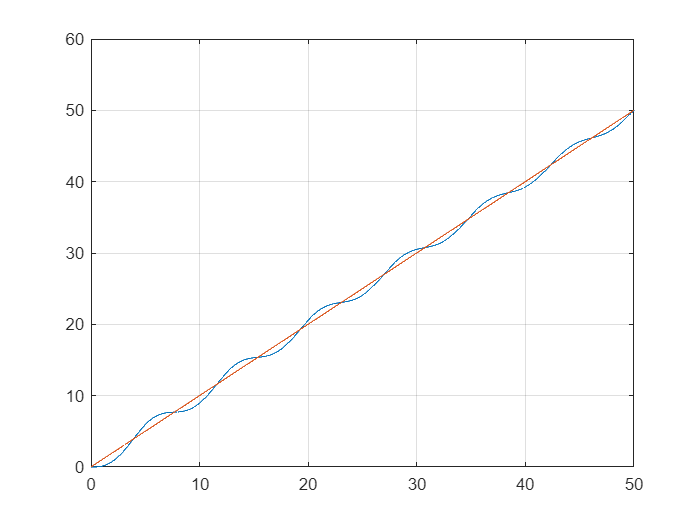

t = 0:0.01:50;
u = t;
num = [1 10]; den = [1 15 0 0]; sys = tf(num,den);
sys_cl = feedback(sys, 1);

y = lsim(sys_cl, u, t);
plot(t, y, t, u), grid

# 5-3

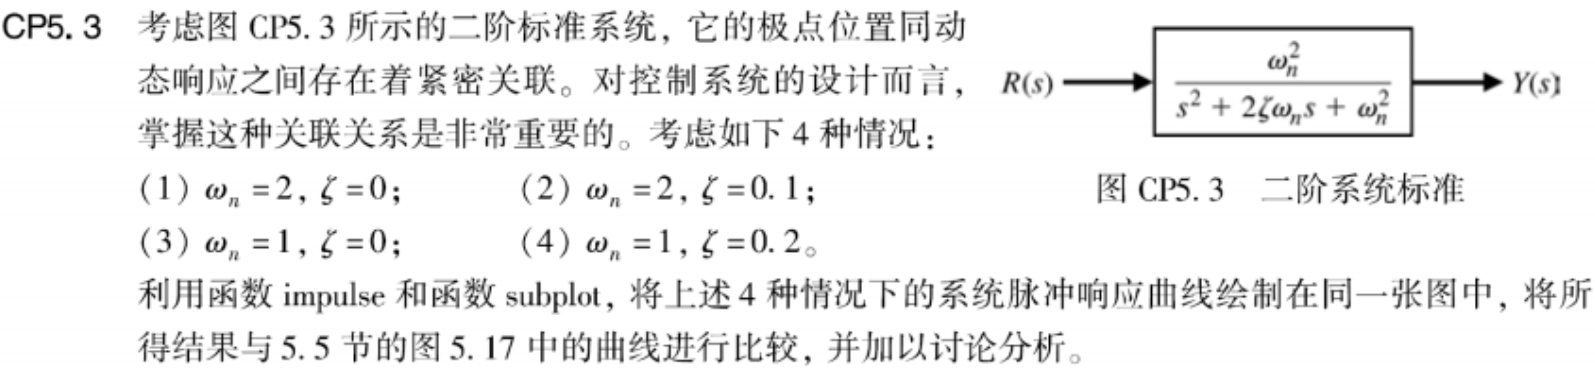

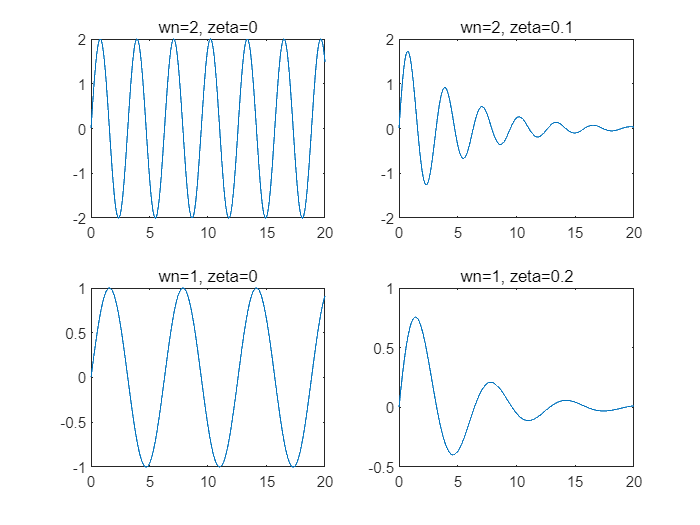

clf

w1 = 2; z1 = 0;
w2 = 2; z2 = 0.1;
w3 = 1; z3 = 0;
w4 = 1; z4 = 0.2;
t = [0:0.01:20];

num1 = [w1^2]; den1 = [1 2*z1*w1 w1^2];
sys1 = tf(num1, den1);
[y1, x1] = impulse(sys1, t);

num2 = [w2^2]; den2 = [1 2*z2*w2 w2^2];
sys2 = tf(num2, den2);
[y2, x2] = impulse(sys2, t);

num3 = [w3^2]; den3 = [1 2*z3*w3 w3^2];
sys3 = tf(num3, den3);
[y3, x3] = impulse(sys3, t);

num4 = [w4^2]; den4 = [1 2*z4*w4 w4^2];
sys4 = tf(num4, den4);
[y4, x4] = impulse(sys4, t);

subplot(221), plot(t, y1), title('wn=2, zeta=0')
subplot(222), plot(t, y2), title('wn=2, zeta=0.1')
subplot(223), plot(t, y3), title('wn=1, zeta=0')
subplot(224), plot(t, y4), title('wn=1, zeta=0.2')

clf

其中 5.5 节的图 5.17 为

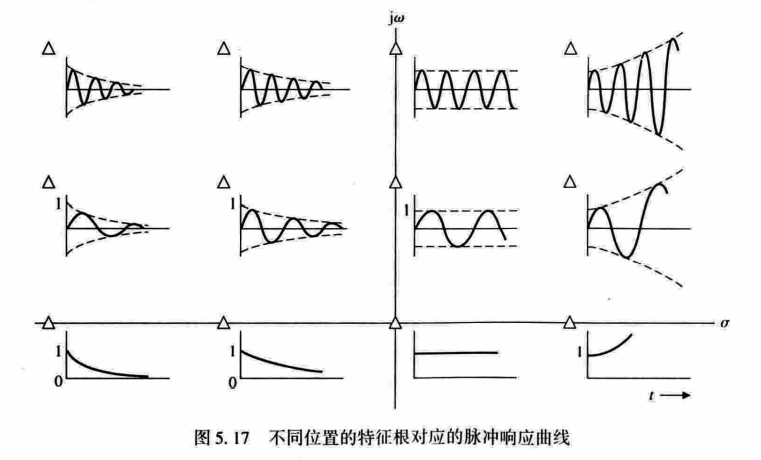

可以看出基本是一致的.

# 5-4

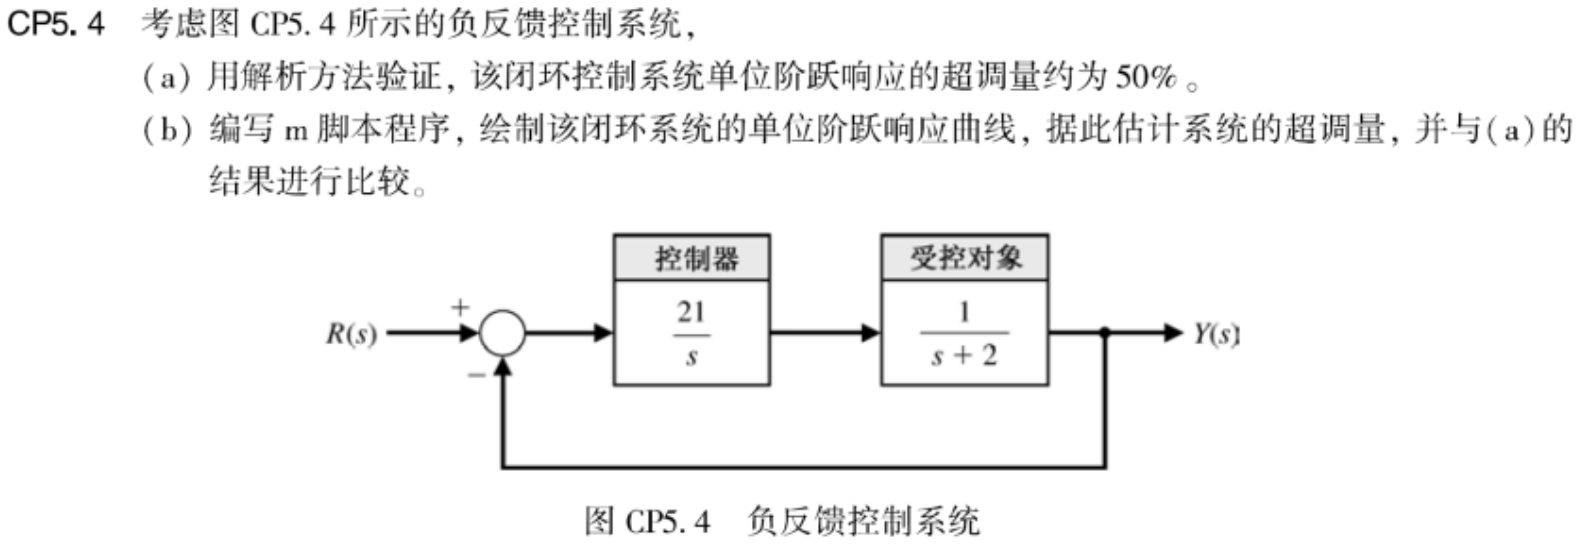

(1)

num1 = [21]; den = [1 0]; sys1 = tf(num1,den);
num2 = [1]; den = [1 2]; sys2 = tf(num2,den);
sys = series(sys1, sys2);
sys_cl = feedback(sys, 1);
sys_cl

sys_cl =
 
        21
  --------------
  s^2 + 2 s + 21
 
Continuous-time transfer function.



`因此该闭环系统的传递函数为`


$$\displaystyle 
T(s) = \frac{21}{s^{2}+2s+21}$$


`由公式 `$\displaystyle \Phi(s) = \frac{\omega_{n}^{2}}{s^{2}+2\zeta \omega_{n}s+\omega_{n}^{2}}$` 可得`


$$\displaystyle 
\omega_{n} = \sqrt{21} = 4.58257569495584$$


`因此有`


$$\displaystyle 
\zeta = \frac{2}{2\omega_{n}} = \frac{1}{\omega_{n}} = \frac{1}{\sqrt{21}} = 0.218217890235992$$


`最后的超调量为`


$$\displaystyle
P.O. = 100e^{-\zeta \pi / \sqrt{1-\zeta^{2}}} = 100e^{-\frac{1}{\sqrt{21}} \pi / \sqrt{1-\frac{1}{21}}} = 49.5354568366144\% \approx 50\%$$


(2)

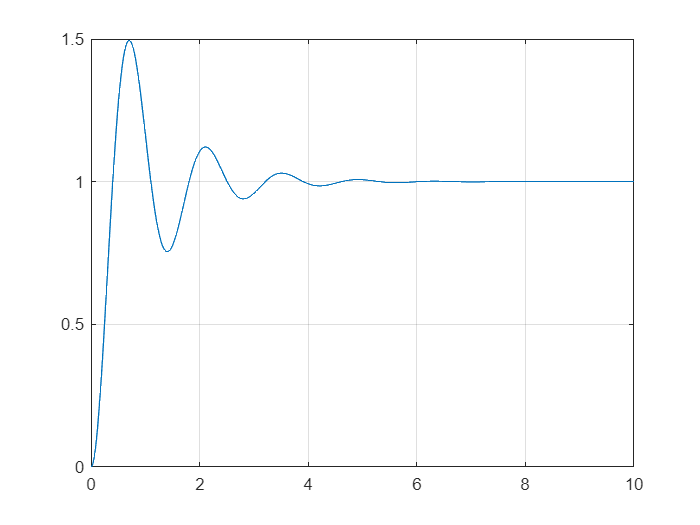

t = 0:0.01:10;
y = step(sys_cl, t);
plot(t, y), grid

因此超调量大约为


$$\displaystyle
P.O. = \frac{1.5-1.0}{1.0} = 50\%$$


# 5-5

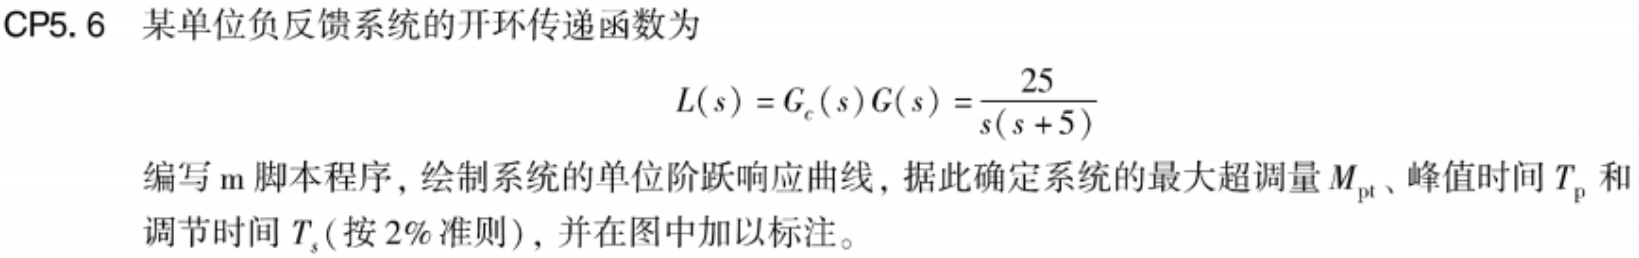

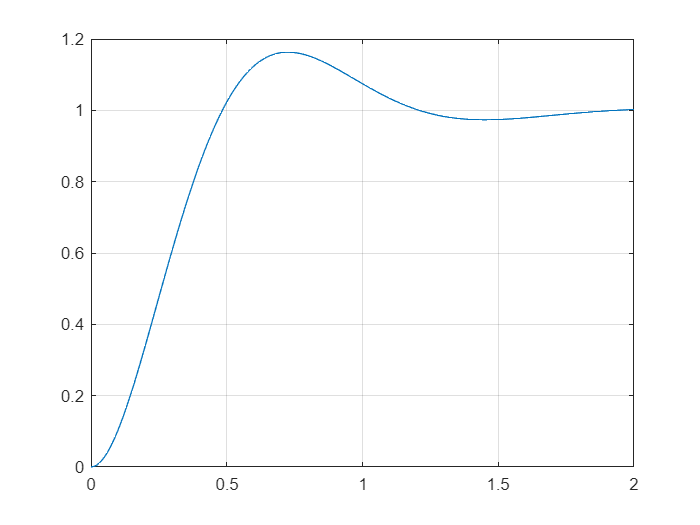

num = [25]; den = [1 5 0]; sys = tf(num,den);
sys_cl = feedback(sys, 1);

t = 0:0.01:2;
y = step(sys_cl, t);
plot(t, y), grid

[m_pt, m_pt_index] = max(y);
m_pt

m_pt = 1.1630

t_p = t(m_pt_index)

t_p = 0.7300

t_s = interp1(y, t, 1 - 0.02)

t_s = 1.6152

因此有

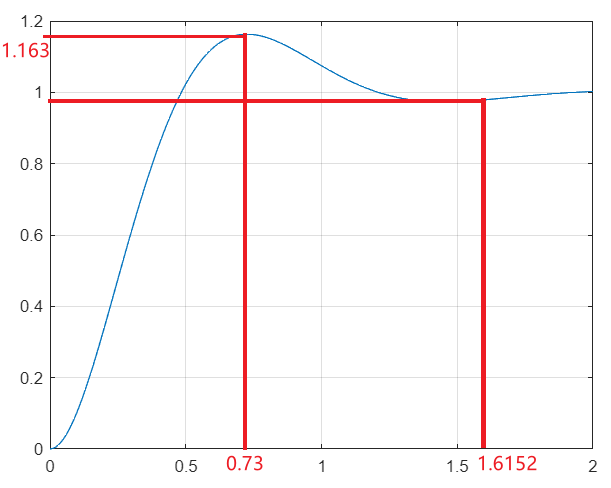

# 5-6

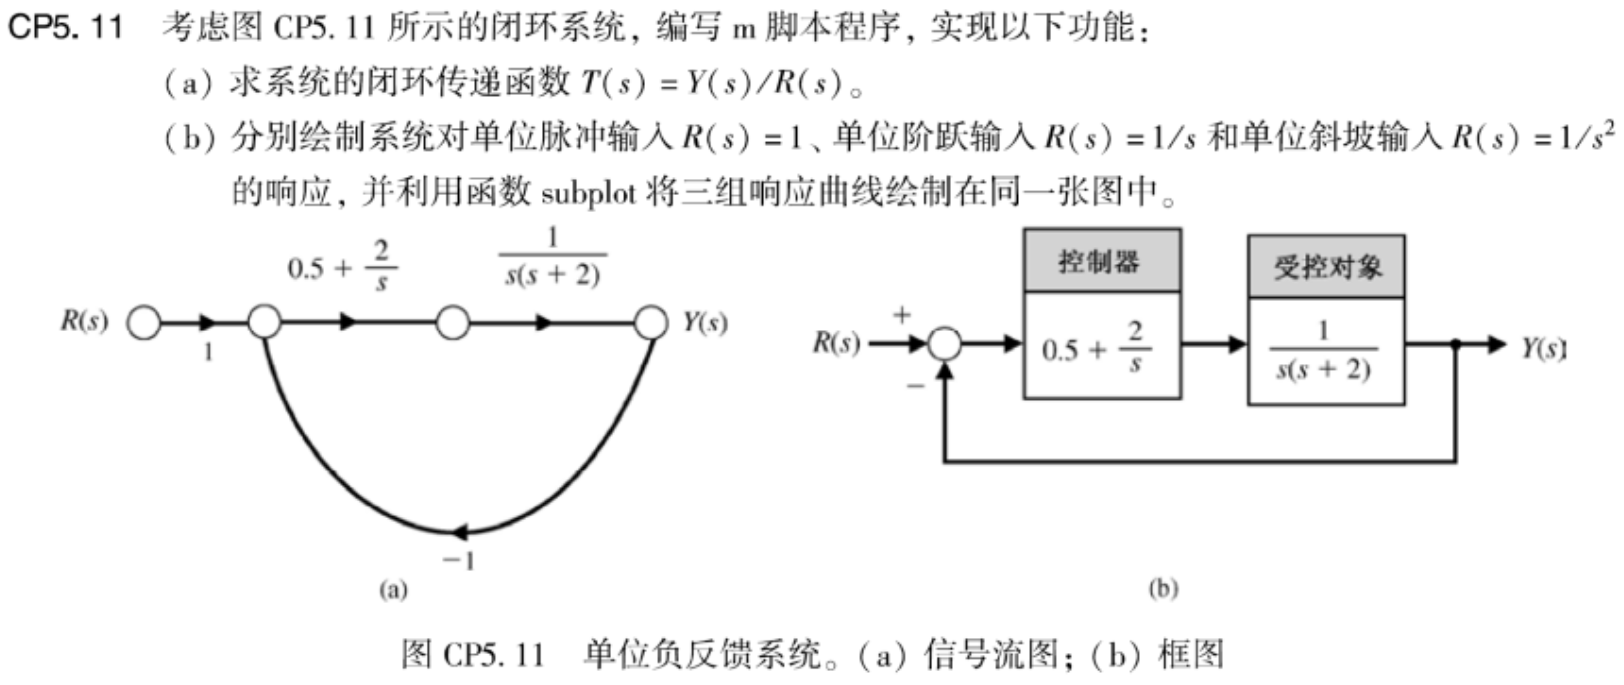

### (a)

num1 = [0.5 2]; den1 = [1 0]; sys1 = tf(num1,den1);
num2 = [1]; den2 = [1 2 0]; sys2 = tf(num2,den2);
sys = series(sys1, sys2);
sys_cl = feedback(sys, 1);
sys_cl

sys_cl =
 
         0.5 s + 2
  -----------------------
  s^3 + 2 s^2 + 0.5 s + 2
 
Continuous-time transfer function.



### (b)

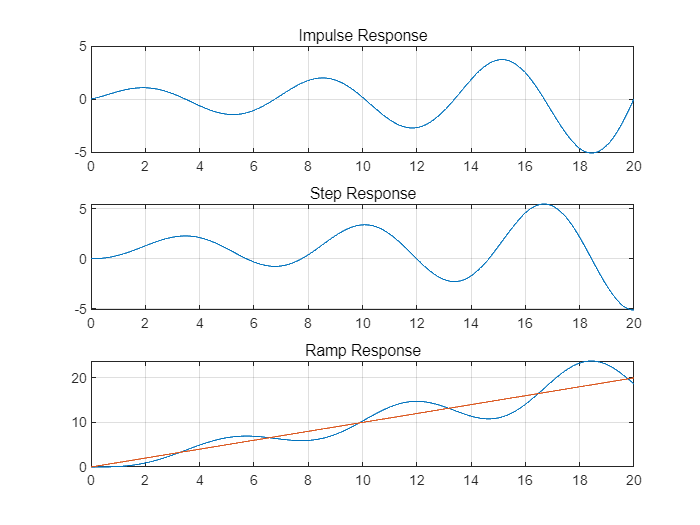

t = 0:0.01:20;
u = t;
y1 = impulse(sys_cl, t);
y2 = step(sys_cl, t);
y3 = lsim(sys_cl, u, t);
subplot(3,1,1), plot(t, y1), grid, title('Impulse Response')
subplot(3,1,2), plot(t, y2), grid, title('Step Response')
subplot(3,1,3), plot(t, y3, t, u), grid, title('Ramp Response')

# 6-1

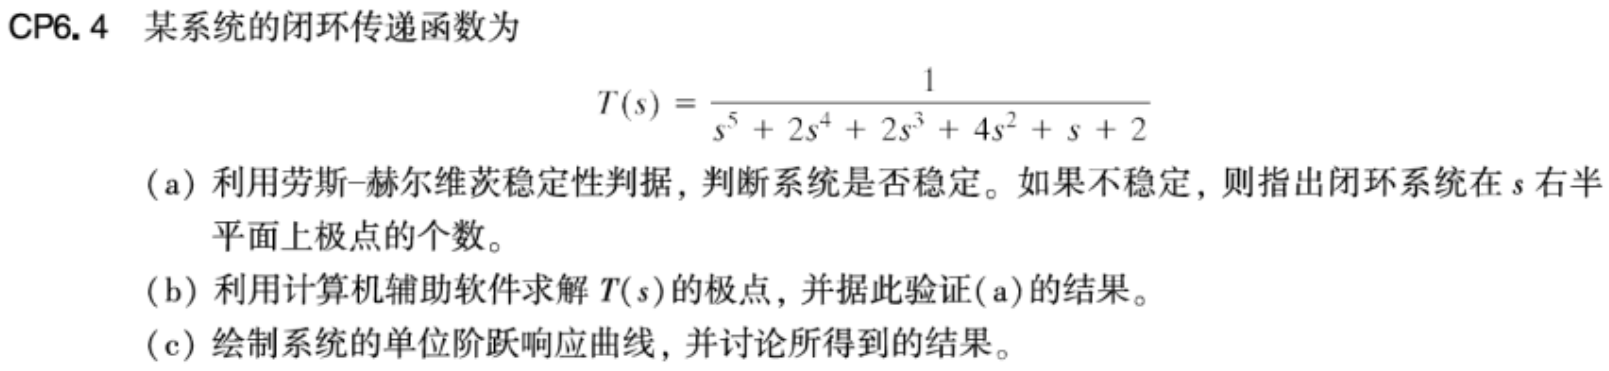

### (a)

劳斯判定表如下


$$\begin{array}{c|ccc}
s^{5} & 1 & 2 & 1 \\
s^{4} & 2 & 4 & 2 \\
s^{4} & 0 & 0 & 0 \\
\end{array}$$


`存在非零行, 因此不稳定.`

`并且我们可知`


$$2s^{4}+4s^{2}+2 = 2 (s^{2} + 1)^{2} = 2 (s + j)^{2}(s - j)^{2}$$


`是特征多项式的一个因子.`


$$\displaystyle 
\frac{s^{5}+2s^{4}+2s^{3}+4s^{2}+s+2}{2s^{4}+4s^{2}+2} = \frac{1}{2}(s+2)$$


`因此有`


$$s^{5}+2s^{4}+2s^{3}+4s^{2}+s+2 = (s+2)(s + j)^{2}(s - j)^{2}$$


因此闭环系统在右半平面上有 0 个极点，在虚轴上有 4 个极点，在左半平面上有 1 个极点.

### (b)

clf

num = 1; den = [1 2 2 4 1 2]; sys = tf(num, den);
pole(sys)

ans =   -2.0000 + 0.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


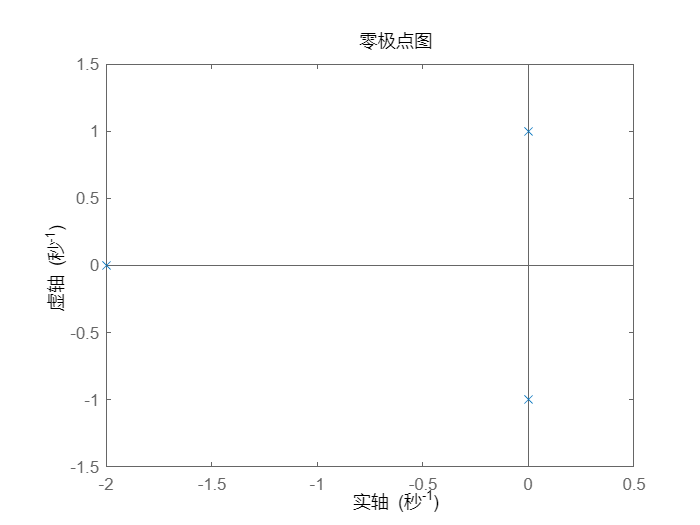

pzmap(sys)

### (c)

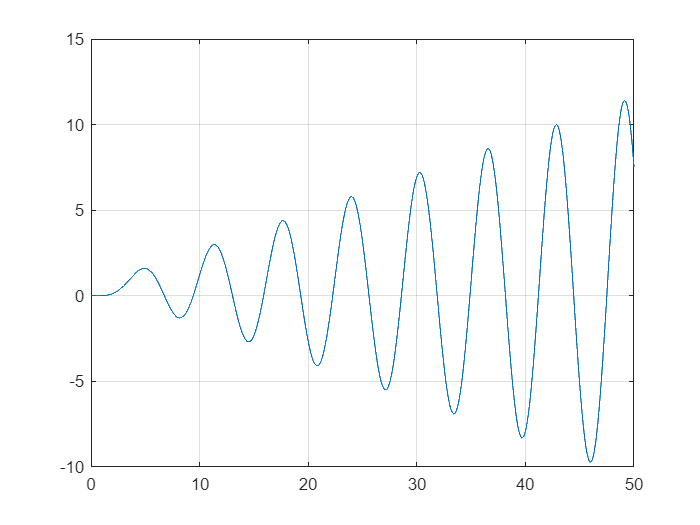

t = 0:0.01:50;
y = step(sys, t);
plot(t, y), grid

可以看出, 单位阶跃响应在不断振荡变大.

# 6-2

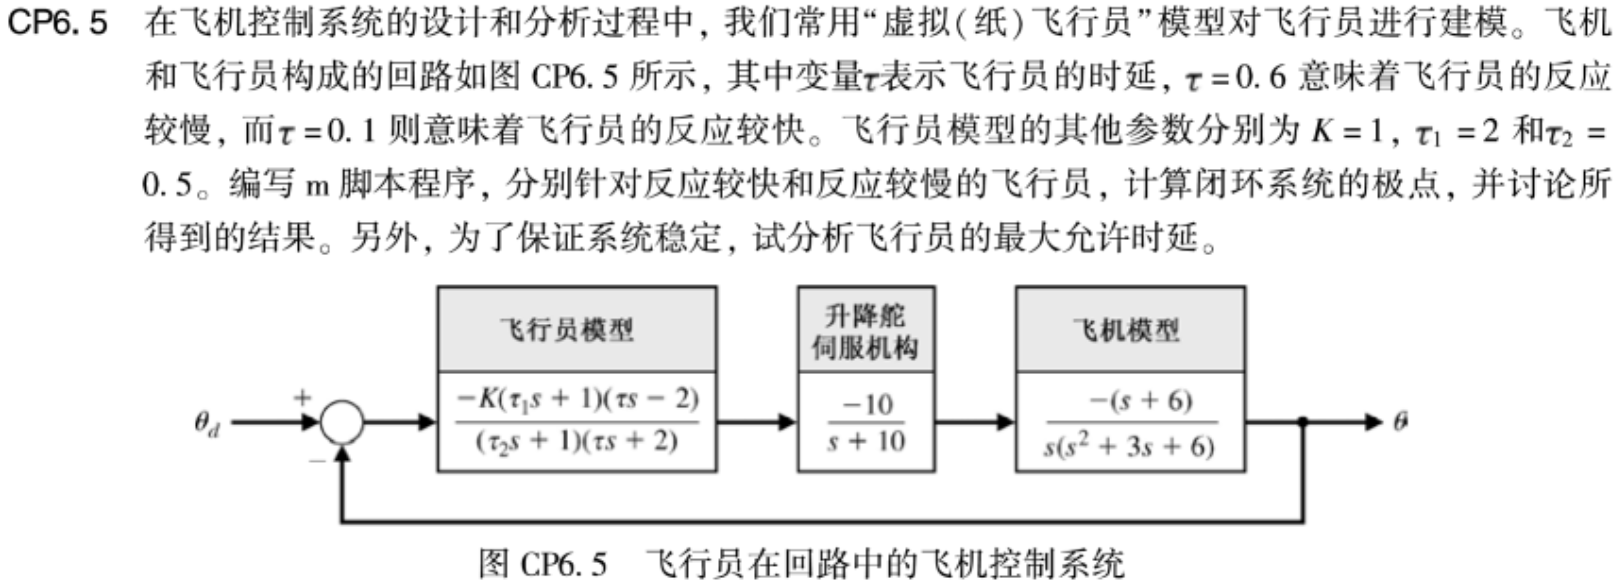

反应较快的飞行员：

clf
sys_fast = get_sys_6_2(0.1)

sys_fast =
 
                    -2 s^3 + 27 s^2 + 254 s + 120
  -----------------------------------------------------------------
  0.05 s^6 + 1.75 s^5 + 18.1 s^4 + 66.6 s^3 + 165 s^2 + 374 s + 120
 
Continuous-time transfer function.



pole(sys_fast)

ans =  -19.6267 + 0.0000i
 -10.7712 + 0.0000i
  -3.8885 + 0.0000i
  -0.1697 + 2.7880i
  -0.1697 - 2.7880i
  -0.3742 + 0.0000i


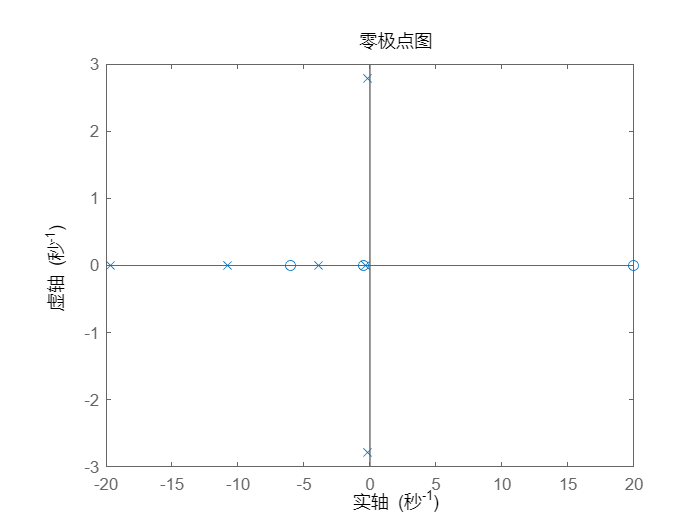

pzmap(sys_fast)

反应较慢的飞行员：

sys_slow = get_sys_6_2(0.6)

sys_slow =
 
                  -12 s^3 - 38 s^2 + 224 s + 120
  ---------------------------------------------------------------
  0.3 s^6 + 5.5 s^5 + 33.6 s^4 + 89.6 s^3 + 130 s^2 + 344 s + 120
 
Continuous-time transfer function.



pole(sys_slow)

ans =   -9.4526 + 0.0000i
  -4.5228 + 2.2595i
  -4.5228 - 2.2595i
   0.2793 + 2.0314i
   0.2793 - 2.0314i
  -0.3937 + 0.0000i


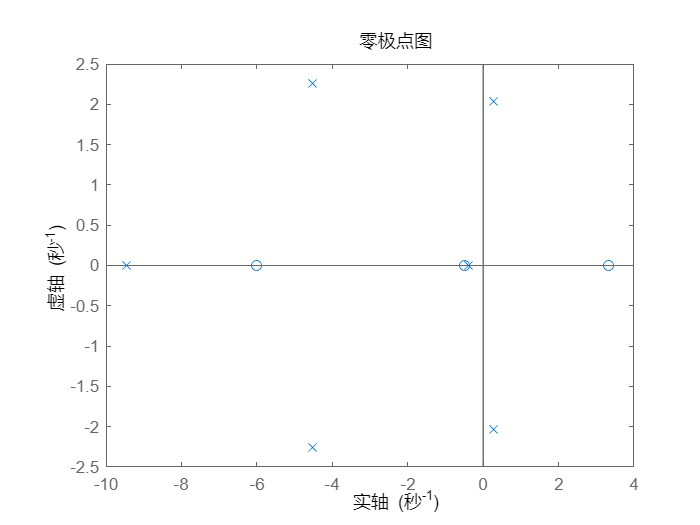

pzmap(sys_slow)

飞行员的最大允许时延：

% find maximum pilot time delay
for tau = 0.1:0.0001:0.6
    sys = get_sys_6_2(tau);
    if max(real(pole(sys))) >= 0
        break
    end
end
tau

tau = 0.2044

sys

sys =
 
                   -4.088 s^3 + 13.43 s^2 + 247.7 s + 120
  -------------------------------------------------------------------------
  0.1022 s^6 + 2.533 s^5 + 21.34 s^4 + 71.4 s^3 + 157.7 s^2 + 367.7 s + 120
 
Continuous-time transfer function.



pole(sys)

ans =  -10.0458 + 2.2686i
 -10.0458 - 2.2686i
  -4.3148 + 0.0000i
   0.0000 + 2.6042i
   0.0000 - 2.6042i
  -0.3783 + 0.0000i


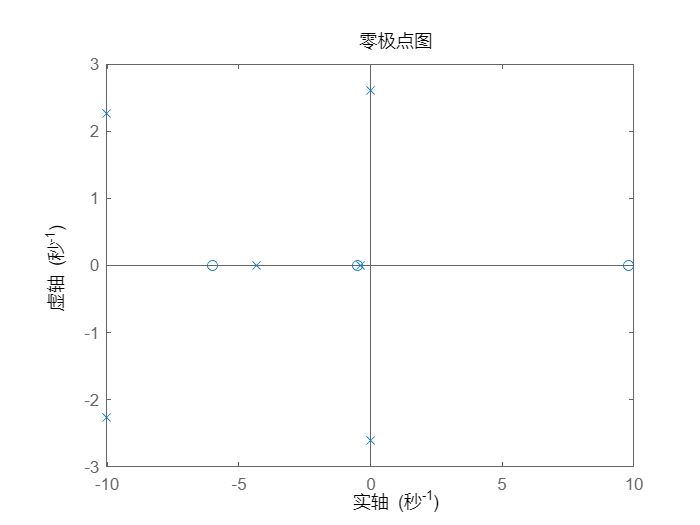

pzmap(sys)

可知最大允许时延为 0.2044 s

由于函数只能放在末尾, 这里我就先注释掉, 然后把函数放末尾了...

% function sys = get_sys_6_2(tau)
%     K = 1; tau1 = 2; tau2 = 0.5;
%     num1 = -K * [tau1*tau tau-2*tau1 -2];
%     den1 = [tau2*tau tau+2*tau2 2];
%     sys1 = tf(num1, den1);
%     num2 = [-10]; den2 = [1 10]; sys2 = tf(num2, den2);
%     num3 = [-1 -6]; den3 = [1 3 6 0]; sys3 = tf(num3, den3);
%     sys = sys1 * sys2 * sys3;
%     sys_cl = feedback(sys, 1);

%     sys = sys_cl;
% end

# 6-3

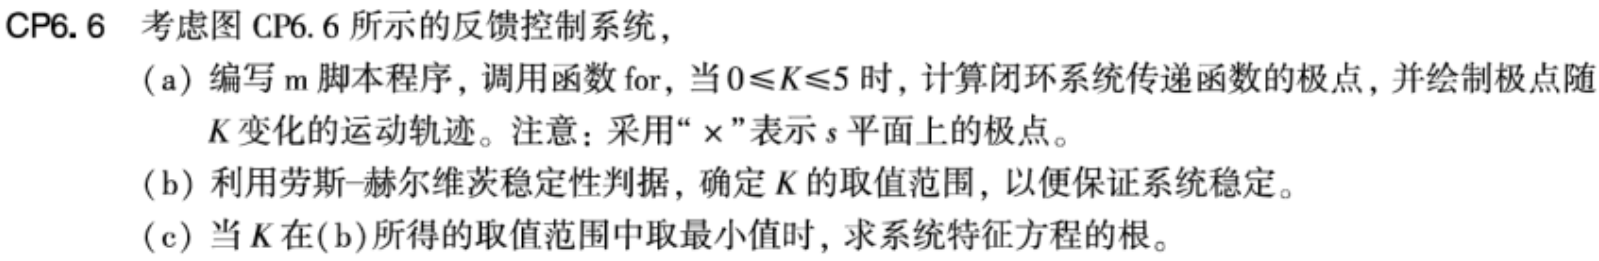

### (a)

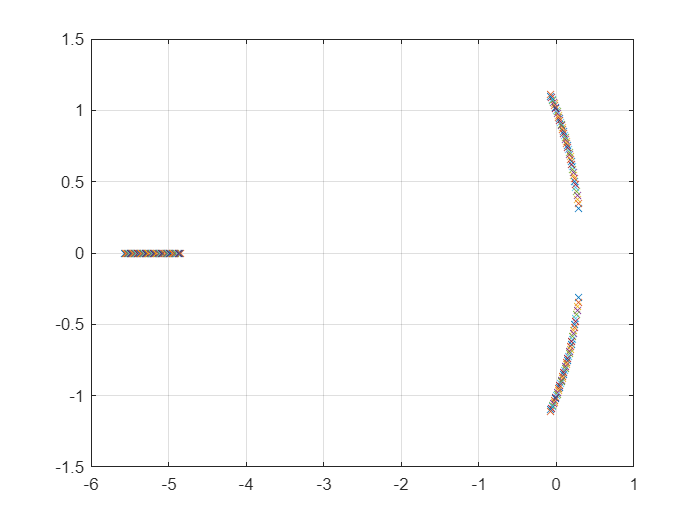

clf
K = 0:0.1:5;
n = length(K);
p = [];
for i = 1:n
    num = [1]; den = [1 5 K(i)-3 K(i)]; sys = tf(num, den);
    sys_cl = feedback(sys, 1);
    p(:, i) = pole(sys_cl);
end
plot(real(p), imag(p), 'x'), grid

### (b)

for i = 1:n
    if max(real(p(:, i))) <= 0
        break
    end
end
p(:,i-1)

ans =   -5.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


K(i-1)

ans = 4

因此可知 K 的范围为 K > 4.

我们用劳斯表判定表也有


$$\begin{array}{c|cc}
s^{3} & 1 & K-3  \\
s^{2} & 5 & K+1  \\
s^{1} & \frac{4}{5}K - \frac{16}{5} & 0  \\
s^{0} & K+1 & 0  \\
\end{array}$$


`因此有 `$\frac{4}{5}K - \frac{16}{5} > 0$` 即 `$K > 4$`.`

### `(c)`

K = K(i-1)

K = 4

num = [1]; den = [1 5 K-3 K]; sys = tf(num, den);
sys_cl = feedback(sys, 1);
p = pole(sys_cl)

p =   -5.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


# 6-4

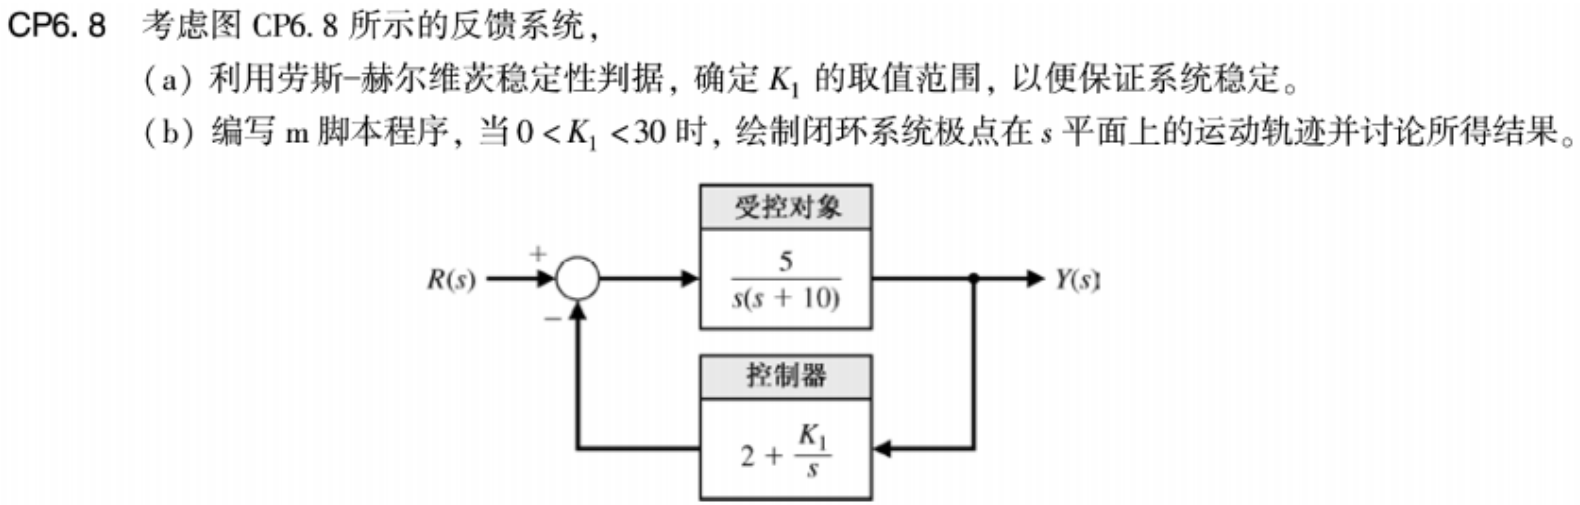

### `(a)`

`反馈系统传递函数:`


$$T(s) = \frac{G(s)}{1+G(s)H(s)}  = \frac{\frac{5}{s(s+10)}}{1+\frac{5}{s(s+10)} \cdot (2+\frac{K_1}{s})}  = \frac{5 s}{s^{3} + 10 s^{2} + 10 s + 5 K_{1}} $$


`可得劳斯判定表:`


$$\begin{array}{c|cc}
s^{3} & 1 & 10  \\
s^{2} & 10 & 5K_1  \\
s^{1} & 10 - \frac{1}{2}K_{1} & 0  \\
s^{0} & 5K_1 & 0  \\
\end{array}$$


`因此有 `$5K_1 > 0$` 与 `$10 - \frac{1}{2}K_{1} > 0$`,`

`即有 `$0 < K_1 < 20$`.`

### `(b)`

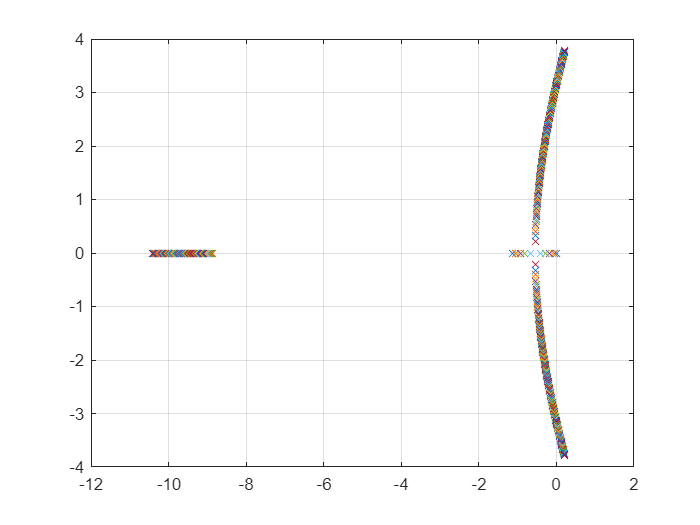

clf
K = 0:0.1:30;
n = length(K);
p = [];
for i = 1:n
    num1 = [5]; den1 = [1 10 0]; sys1 = tf(num1, den1);
    num2 = [2 K(i)]; den2 = [1 0]; sys2 = tf(num2, den2);
    sys_cl = feedback(sys1, sys2);
    p(:, i) = pole(sys_cl);
end
plot(real(p), imag(p), 'x'), grid

K = 20;
num1 = [5]; den1 = [1 10 0]; sys1 = tf(num1, den1);
num2 = [2 K]; den2 = [1 0]; sys2 = tf(num2, den2);
sys_cl = feedback(sys1, sys2);
pole(sys_cl)

ans =  -10.0000 + 0.0000i
   0.0000 + 3.1623i
   0.0000 - 3.1623i


可以看出，确实是在 K > 20 的时候，极点移动到了右半平面.

# 函数定义

最后放了一些函数定义，因为脚本不允许把函数放在前面...

2.1

% 1. calculate transfer function
function sys = get_sys_2_1(J, k, a, b)
    num1 = [k, k * a];
    den1 = [1, b];
    num2 = 1;
    den2 = [J, 0, 0];

    [num, den] = series(num1, den1, num2, den2);
    [num, den] = feedback(num, den, 1, 1, -1);
    sys = tf(num, den);
end


% 2. draw the curve with step sinal A = 10
function y = get_y_2_1(sys, t)
    opt = stepDataOptions('StepAmplitude', 10);
    [y, ~] = step(sys, t, opt);
end

2.4

% 1. calculate transfer function
function sys = get_sys_2_3(z)
    num = [20 / z, 20];
    den = [1, 3, 20];
    sys = tf(num, den);
end


% 2. draw the curve with step sinal
function y = get_y_2_3(sys, t)
    [y, ~] = step(sys, t);
end

6.2

function sys = get_sys_6_2(tau)
    K = 1; tau1 = 2; tau2 = 0.5;
    num1 = -K * [tau1*tau tau-2*tau1 -2];
    den1 = [tau2*tau tau+2*tau2 2];
    sys1 = tf(num1, den1);
    num2 = [-10]; den2 = [1 10]; sys2 = tf(num2, den2);
    num3 = [-1 -6]; den3 = [1 3 6 0]; sys3 = tf(num3, den3);
    sys = sys1 * sys2 * sys3;
    sys_cl = feedback(sys, 1);

    sys = sys_cl;
end